clc; clearvars;

set altitude grid and calculate air number density

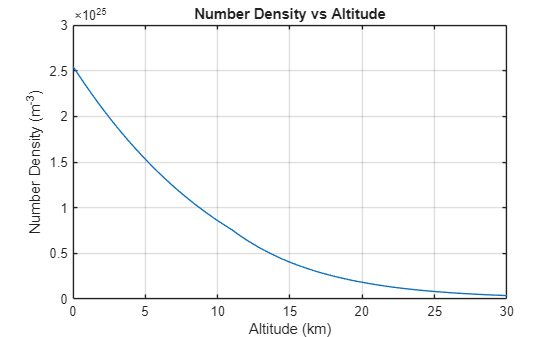

z = linspace(0,30e3,1e3);
z_km = z./1000;

N = airNumberDensity(z);

figure;
plot(z_km,N)
xlabel('Altitude (km)');
ylabel('Number Density (m^{-3})');
title('Number Density vs Altitude');
grid on;

index of refraction of medium, n1 and particles, n

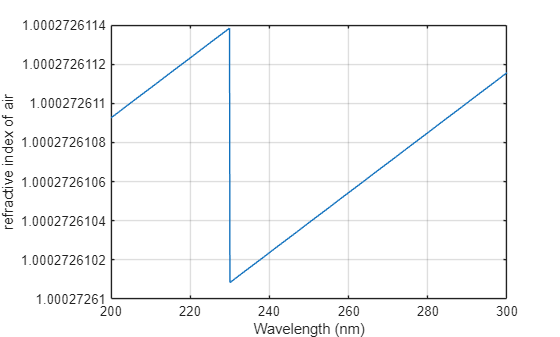

test_lams = linspace(200e-9,300e-9,1000);
figure;
plot(test_lams .* 1e9 ,indexOfRefraction(test_lams))
xlabel("Wavelength (nm)")
ylabel("refractive index of air")
grid on

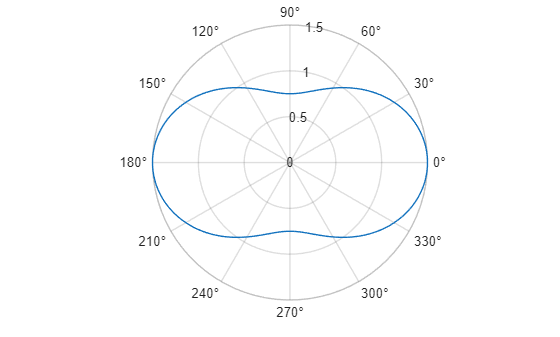

test_theta = linspace(0,2*pi,1000);
figure;
polarplot(test_theta,rayleighPhaseFunction(test_theta))

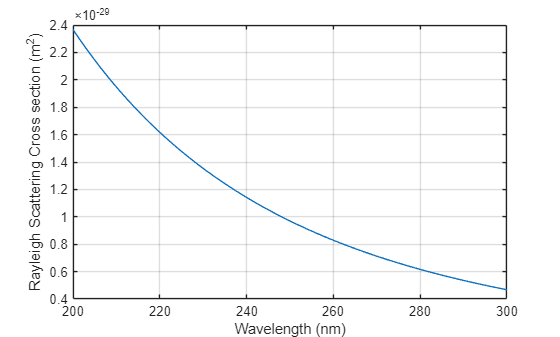

figure;
plot(test_lams .* 1e9 ,rayleighCross(test_lams))
xlabel("Wavelength (nm)")
ylabel("Rayleigh Scattering Cross section (m^2)")
grid on

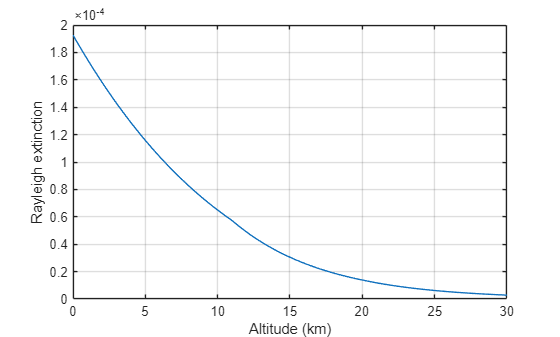

c_266 = rayleighCross(266e-9);

figure;
plot(z_km, sectionToCoefficient(c_266,N))
xlabel("Altitude (km)")
ylabel("Rayleigh extinction")
grid on;

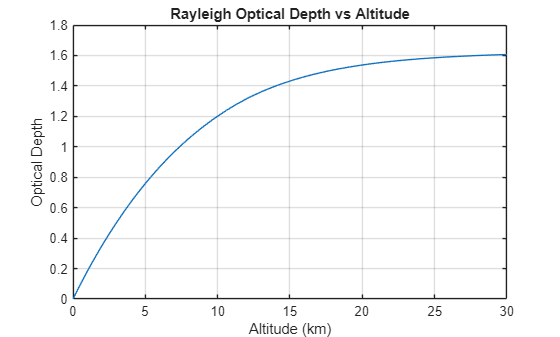

tau = rayleighOD(c_266, N, z);
figure;
plot(z_km, tau);
xlabel('Altitude (km)');
ylabel('Optical Depth');
title('Rayleigh Optical Depth vs Altitude');
grid on;

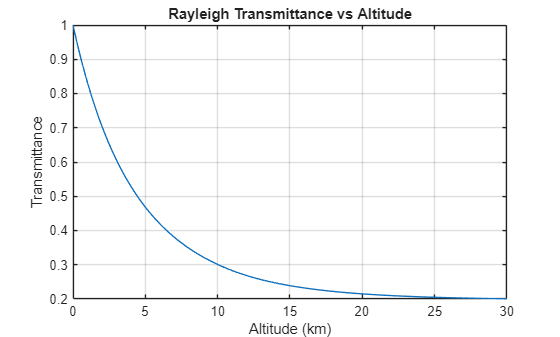

alpha = rayleightransmittance(tau);
figure;
plot(z_km, alpha);
xlabel('Altitude (km)');
ylabel('Transmittance');
title('Rayleigh Transmittance vs Altitude');
grid on;

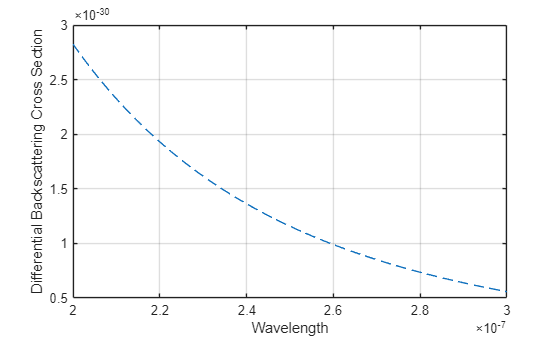

B = rayleighBackscatterCross(test_lams);

figure;
plot(test_lams,B,'--')
xlabel('Wavelength');
ylabel('Differential Backscattering Cross Section');
title('');
grid on;